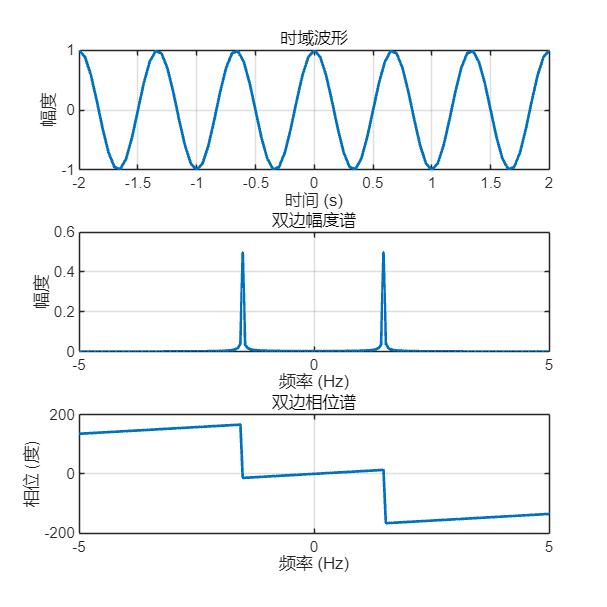


t = -10:0.05:10;
Ts = 0.05;               
Fs = 1/Ts;              
L = length(t);          


f = cos(3*pi*t);         

Y = fft(f);


f_axis = (-L/2:L/2-1)*(Fs/L);  


Y_shifted = fftshift(Y);     
magnitude = abs(Y_shifted/L);   


phase = angle(Y_shifted);      
phase = unwrap(phase);   

figure('Position', [100, 100, 1000, 1000])


subplot(3,1,1)
plot(t, f, 'LineWidth', 1.5)
title('时域波形')
xlabel('时间 (s)')
ylabel('幅度')
grid on
xlim([-2 2])  


subplot(3,1,2)
plot(f_axis, magnitude, 'LineWidth', 1.5)
title('双边幅度谱')
xlabel('频率 (Hz)')
ylabel('幅度')
grid on
xlim([-5 5])  


subplot(3,1,3)
plot(f_axis, rad2deg(phase), 'LineWidth', 1.5)  % 转换为度数显示
title('双边相位谱')
xlabel('频率 (Hz)')
ylabel('相位 (度)')
grid on
xlim([-5 5])

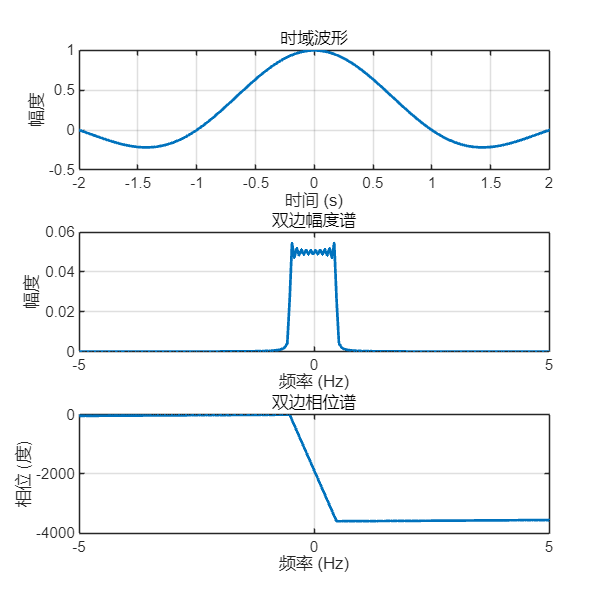


t = -10:0.05:10;
Ts = 0.05;               
Fs = 1/Ts;              
L = length(t);          


f = sinc(t);         

Y = fft(f);


f_axis = (-L/2:L/2-1)*(Fs/L);  


Y_shifted = fftshift(Y);     
magnitude = abs(Y_shifted/L);   


phase = angle(Y_shifted);      
phase = unwrap(phase);   

figure('Position', [100, 100, 1000, 1000])


subplot(3,1,1)
plot(t, f, 'LineWidth', 1.5)
title('时域波形')
xlabel('时间 (s)')
ylabel('幅度')
grid on
xlim([-2 2])  


subplot(3,1,2)
plot(f_axis, magnitude, 'LineWidth', 1.5)
title('双边幅度谱')
xlabel('频率 (Hz)')
ylabel('幅度')
grid on
xlim([-5 5])  


subplot(3,1,3)
plot(f_axis, rad2deg(phase), 'LineWidth', 1.5) 
title('双边相位谱')
xlabel('频率 (Hz)')
ylabel('相位 (度)')
grid on
xlim([-5 5])

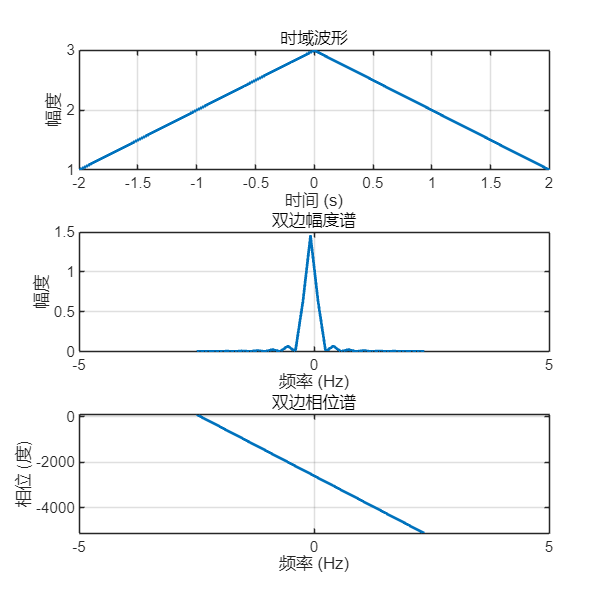


t = -3:0.2:3;
Ts = 0.2;               
Fs = 1/Ts;              
L = length(t);          


f = zeros(size(t));
f((t>=-3)&(t<=0)) = t((t>=-3)&(t<=0)) + 3;
f((t>=0)&(t<=3)) = -t((t>=0)&(t<=3)) + 3;


Y = fft(f);


f_axis = (-L/2:L/2-1)*(Fs/L);  


Y_shifted = fftshift(Y);     
magnitude = abs(Y_shifted/L);   


phase = angle(Y_shifted);      
phase = unwrap(phase);   

figure('Position', [100, 100, 1000, 1000])


subplot(3,1,1)
plot(t, f, 'LineWidth', 1.5)
title('时域波形')
xlabel('时间 (s)')
ylabel('幅度')
grid on
xlim([-2 2])  


subplot(3,1,2)
plot(f_axis, magnitude, 'LineWidth', 1.5)
title('双边幅度谱')
xlabel('频率 (Hz)')
ylabel('幅度')
grid on
xlim([-5 5])  


subplot(3,1,3)
plot(f_axis, rad2deg(phase), 'LineWidth', 1.5)  % 转换为度数显示
title('双边相位谱')
xlabel('频率 (Hz)')
ylabel('相位 (度)')
grid on
xlim([-5 5])

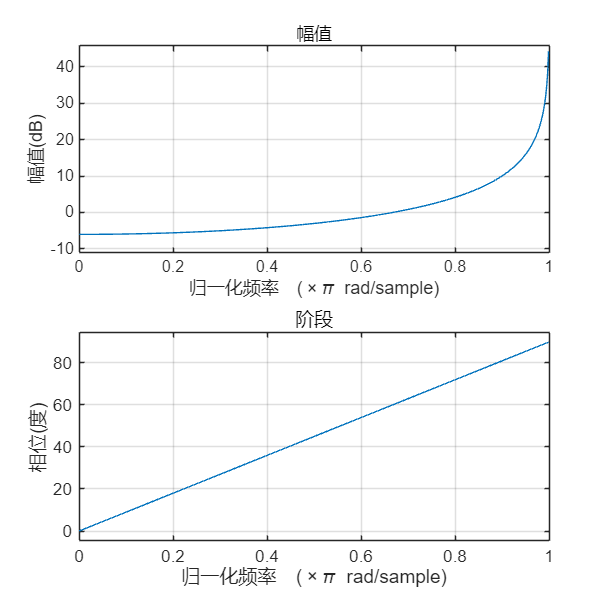

%Q2
num1 = [1 0];       
den1 = [1 1];       
freqz(num1,den1);

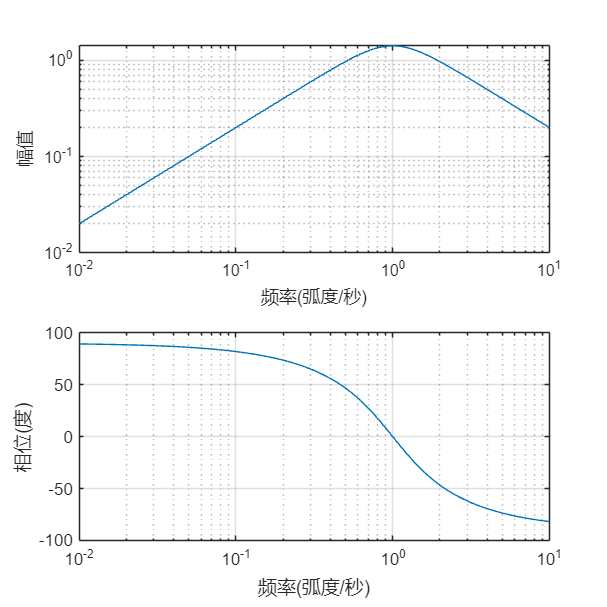


num2 = [0 2 0];
den2 = [1 sqrt(2) 1];
freqs(num2,den2);

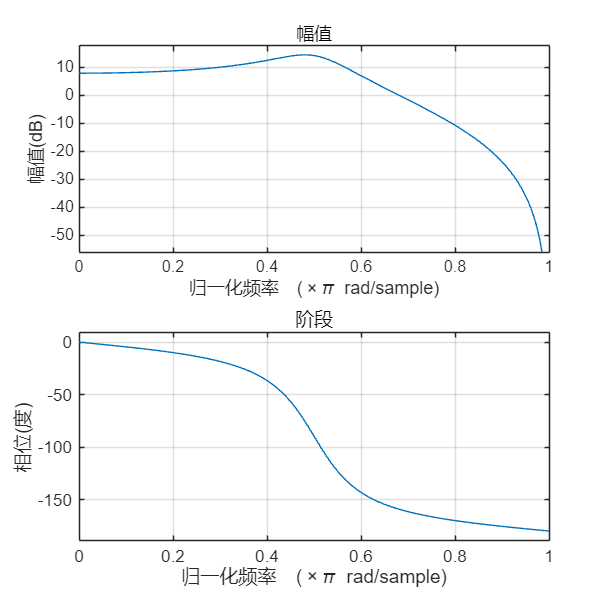


num3 = [1 2 1];
den3 = [1 0 0.61];
freqz(num3,den3);

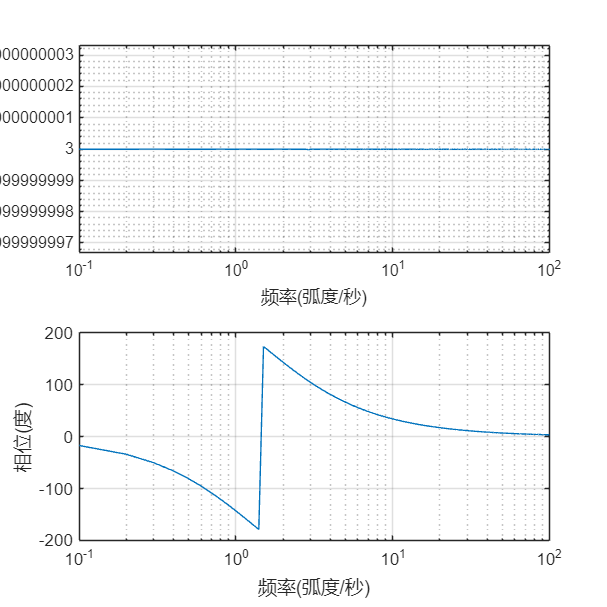


num4 = [3 -9 6];
den4 = [1 3 2];
w =linspace(0.1,100,1000);
freqs(num4,den4,w);

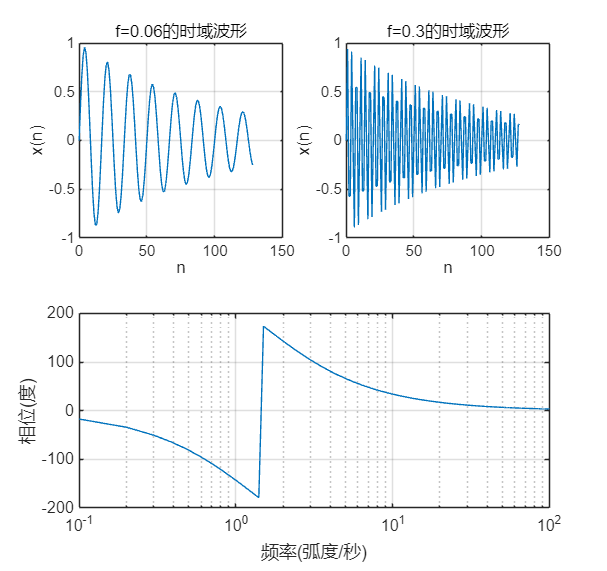

%Q3
n = 0:128;
a = 0.1;
f1 = 0.06;
f2 = 0.3;
x1 = exp(-0.1*a*n).*sin(2*pi*f1*n);
x2 = exp(-0.1*a*n).*sin(2*pi*f2*n);

subplot(2,2 ,1);
plot(n,x1);
xlabel("n");
ylabel("x(n)");
title("f=0.06的时域波形");
grid on;

subplot(2,2,2);
plot(n,x2);
xlabel("n");
ylabel("x(n)");
title("f=0.3的时域波形");
grid on;

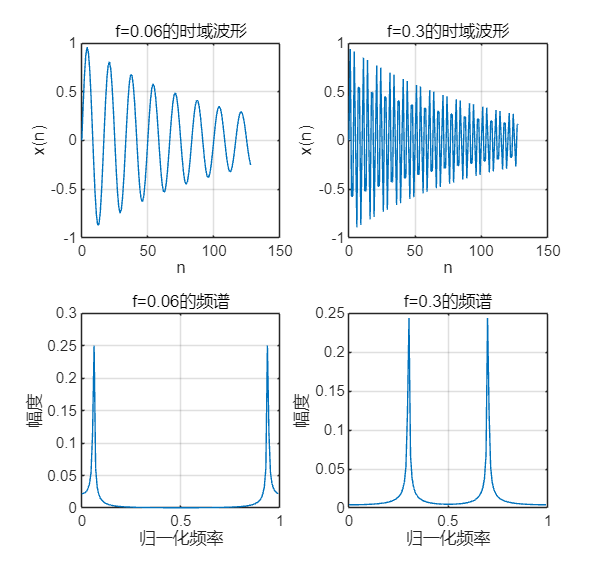


N = length(n);
X1 = abs(fft(x1))/N;  % 归一化
X2 = abs(fft(x2))/N;

f = (0:N-1)/N;

subplot(2,2,3);
plot(f,X1);
xlabel('归一化频率');
ylabel('幅度');
title('f=0.06的频谱');
grid on;
%xlim([0 0.5]);  % 只显示0-0.5的频率范围

subplot(2,2,4);
plot(f,X2);
xlabel('归一化频率');
ylabel('幅度');
title('f=0.3的频谱');
grid on;

%xlim([0 0.5]);  % 只显示0-0.5的频率范围

%{
f= 0.3的频谱在0.3,0.7有峰值，f = 0.06频谱在0.06和0.94有峰值。
原因是频率值的大小决定了频谱中峰值的位置，而且关于0.5对称。

%}
